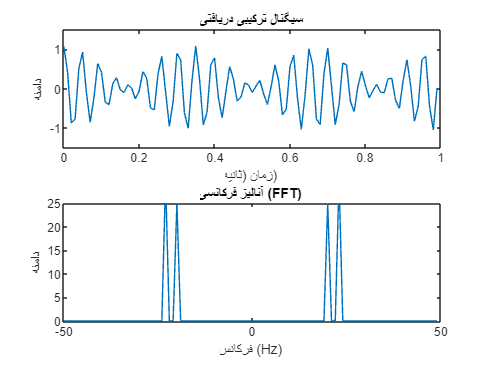

% پارامترهای اولیه
t_start = 0;
t_end = 1;
f_c = 5; % فرکانس سیگنال اصلی
f_s = 100; % فرکانس نمونه‌برداری

% تولید بردار زمان
t_s = 1/f_s;
t = t_start: t_s:t_end-t_s;

% پارامترهای جسم 1
R1 = 250e3; % فاصله (متر)
V1 = 180 * 1000 / 3600; % سرعت (متر بر ثانیه)
alpha1 = 0.5; % دامنه
f_d1 = V1 * 0.3; % فرکانس داپلر
t_d1 = (2 * R1) / (3 * 10^8); % زمان تأخیر

% پارامترهای جسم 2
R2 = 200e3; % فاصله (متر)
V2 = 216 * 1000 / 3600; % سرعت (متر بر ثانیه)
alpha2 = 0.6; % دامنه
f_d2 = V2 * 0.3; % فرکانس داپلر
t_d2 = (2 * R2) / (3 * 10^8); % زمان تأخیر

% تولید سیگنال‌های جسم 1 و 2
y1 = alpha1 * cos(2*pi*(f_c + f_d1) * (t - t_d1));
y2 = alpha2 * cos(2*pi*(f_c + f_d2) * (t - t_d2));

% ترکیب سیگنال‌ها
y = y1 + y2;

% نمایش سیگنال ترکیبی
figure;
subplot(2,1,1);
plot(t, y);
xlim([0 1]);
ylim([-1.5 1.5]);
xlabel("زمان (ثانیه)");
ylabel("دامنه");
title("سیگنال ترکیبی دریافتی");

% محاسبه FFT
f = -f_s/2 : 1 : (f_s/2) - 1;
z = fftshift(fft(y));

% نمایش FFT
subplot(2,1,2);
plot(f, abs(z));
xlim([-50 50]);
ylim([0 25]);
xlabel("فرکانس (Hz)");
ylabel("دامنه");
title("آنالیز فرکانسی (FFT)");


% پیدا کردن پیک‌های فرکانسی
threshold_size = max(abs(z)) / 2;
[pks, locs] = findpeaks(abs(z), "MinPeakHeight", threshold_size);

% استخراج فاز پیک‌ها
phaz = zeros(size(locs));
for i = 1:length(locs)
    phaz(i) = angle(z(locs(i)));
end

% محاسبه زمان پرواز از فاز
if length(phaz) >= 2
    t_d_out1 = phaz(1) / (2 * pi * f_d1);
    t_d_out2 = phaz(2) / (2 * pi * f_d2);
else
    t_d_out1 = NaN; % اگر تعداد پیک‌ها کافی نباشد
    t_d_out2 = NaN; % اگر تعداد پیک‌ها کافی نباشد
end

% محاسبه فاصله تخمینی
d_estimated1 = (3 * 10^8 * t_d_out1) / 2;
d_estimated2 = (3 * 10^8 * t_d_out2) / 2;

% نمایش نتایج
fprintf('فرکانس داپلر جسم 1 تخمینی: %.2f Hz\n', f_d1);

فرکانس داپلر جسم 1 تخمینی: 15.00 Hz


fprintf('زمان پرواز جسم 1 تخمینی: %.2e s\n', t_d_out1);

زمان پرواز جسم 1 تخمینی: 2.04e-03 s


fprintf('فاصله جسم 1 تخمینی: %.2f m\n', d_estimated1);

فاصله جسم 1 تخمینی: 306666.67 m



fprintf('فرکانس داپلر جسم 2 تخمینی: %.2f Hz\n', f_d2);

فرکانس داپلر جسم 2 تخمینی: 18.00 Hz


fprintf('زمان پرواز جسم 2 تخمینی: %.2e s\n', t_d_out2);

زمان پرواز جسم 2 تخمینی: 1.85e-03 s


fprintf('فاصله جسم 2 تخمینی: %.2f m\n', d_estimated2);

فاصله جسم 2 تخمینی: 277777.78 m
